% 八棱柱的参数
num_points = 100; % 每个面上的点数
side_length = 1; % 八棱柱的边长
epsilon = 0.01; % 小的扰动

% 八边形顶面和底面的点坐标
theta = linspace(0, 2*pi, 9); % 八边形角度
x = side_length/2 * cos(theta); % x坐标
y = side_length/2 * sin(theta); % y坐标
z_top = side_length/2 * ones(size(x)); % 顶面z坐标
z_bottom = -side_length/2 * ones(size(x)); % 底面z坐标

% 初始化每个面的点
top_face = zeros(num_points, 3);
bottom_face = zeros(num_points, 3);
side_faces = zeros(num_points*8, 3); % 8个侧面，每个面num_points个点

% 生成顶面和底面的点
for i = 1:num_points
    % 顶面
    top_face(i, :) = [side_length * (rand() - 0.5), side_length * (rand() - 0.5), z_top(1) + epsilon * (rand() - 0.5)];
    
    % 底面
    bottom_face(i, :) = [side_length * (rand() - 0.5), side_length * (rand() - 0.5), z_bottom(1) + epsilon * (rand() - 0.5)];
end

% 生成侧面的点
z_min = -0.5; % z坐标最小值
z_max = 0.5;  % z坐标最大值

for i = 1:8
    % 顶面点
    p1 = [x(i), y(i), z_top(1)];
    p2 = [x(i+1), y(i+1), z_top(1)];
    % 底面点
    p3 = [x(i), y(i), z_bottom(1)];
    p4 = [x(i+1), y(i+1), z_bottom(1)];
    
    % 生成每个侧面的点
    for j = 1:num_points
        % 在每个侧面矩形内生成点
        t = (j-1)/(num_points-1); % 在矩形的高度方向上均匀分布
        x_side = (1 - t) * p1(1) + t * p2(1) + epsilon * (rand() - 0.5);
        y_side = (1 - t) * p1(2) + t * p2(2) + epsilon * (rand() - 0.5);
        z_side = z_min + (z_max - z_min) * rand(); % z坐标在指定范围内随机分布
        side_faces((i-1)*num_points + j, :) = [x_side, y_side, z_side];
    end
end

% 合并所有点
points = [top_face; bottom_face; side_faces];

% 旋转和位移
theta_z = pi/6; % 绕z轴的旋转角度
theta_x = pi/6; % 绕x轴的旋转角度

% 绕z轴旋转的矩阵
R_z = [cos(theta_z) -sin(theta_z) 0;
       sin(theta_z)  cos(theta_z) 0;
       0            0           1];

% 绕x轴旋转的矩阵
R_x = [1      0              0;
       0  cos(theta_x) -sin(theta_x);
       0  sin(theta_x)  cos(theta_x)];

% 总旋转矩阵为 R_x * R_z
R = R_x * R_z;

T = [0.1, 0.1, 0.1]; % 位移向量

% 应用旋转和位移
points_rot_trans = (R * points')' + T;

% 提取每个面的新坐标
top_face_transformed = points_rot_trans(1:num_points, :);
bottom_face_transformed = points_rot_trans(num_points+1:2*num_points, :);
side_faces_transformed = points_rot_trans(2*num_points+1:end, :);

% 将侧面点分开
side_faces_transformed1 = side_faces_transformed(1:num_points, :);
side_faces_transformed2 = side_faces_transformed(num_points+1:2*num_points, :);
side_faces_transformed3 = side_faces_transformed(2*num_points+1:3*num_points, :);
side_faces_transformed4 = side_faces_transformed(3*num_points+1:4*num_points, :);
side_faces_transformed5 = side_faces_transformed(4*num_points+1:5*num_points, :);
side_faces_transformed6 = side_faces_transformed(5*num_points+1:6*num_points, :);
side_faces_transformed7 = side_faces_transformed(6*num_points+1:7*num_points, :);
side_faces_transformed8 = side_faces_transformed(7*num_points+1:end, :);

% 拟合每个面的平面
planes = zeros(8, 4); % 8个面

% 顶面
f_top = fit([top_face_transformed(:, 1), top_face_transformed(:, 2)], top_face_transformed(:, 3), 'poly11');
planes(1, :) = [f_top.p10, f_top.p01, -1, f_top.p00];

% 底面
f_bottom = fit([bottom_face_transformed(:, 1), bottom_face_transformed(:, 2)], bottom_face_transformed(:, 3), 'poly11');
planes(2, :) = [f_bottom.p10, f_bottom.p01, -1, f_bottom.p00];

% 侧面拟合
for i = 1:8
    % 对于每个侧面，x或y固定，拟合剩下的两个维度
    if mod(i, 2) == 1
        % 侧面x固定
        f_side = fit([eval(['side_faces_transformed', num2str(i), '(:, 2)']), ...
                      eval(['side_faces_transformed', num2str(i), '(:, 3)'])], ...
                     eval(['side_faces_transformed', num2str(i), '(:, 1)']), 'poly11');
        planes(i+2, :) = [-1, f_side.p10, f_side.p01, f_side.p00];
    else
        % 侧面y固定
        f_side = fit([eval(['side_faces_transformed', num2str(i), '(:, 2)']), ...
                      eval(['side_faces_transformed', num2str(i), '(:, 3)'])], ...
                     eval(['side_faces_transformed', num2str(i), '(:, 1)']), 'poly11');
        planes(i+2, :) = [f_side.p10, -1, f_side.p01, f_side.p00];
    end
end

% 显示结果
disp('每个面的平面参数 (a, b, c, d):');

每个面的平面参数 (a, b, c, d):


disp(planes);

    0.0009    0.5770   -1.0000    0.6198
    0.0010    0.5783   -1.0000   -0.5362
   -1.0000   -1.1278   -0.6544    1.0371
    6.2538   -1.0000    3.6211   -4.2577
   -1.0000    0.6574    0.3799   -0.5837
   -0.1148   -1.0000   -0.0660   -0.3477
   -1.0000   -1.1276   -0.6494   -0.4804
    6.2546   -1.0000    3.5984    2.4804
   -1.0000    0.6664    0.3849    0.5782
   -0.1109   -1.0000   -0.0631    0.5832



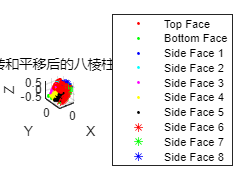


% 可视化
figure;
scatter3(top_face_transformed(:,1), top_face_transformed(:,2), top_face_transformed(:,3), 'r.', 'DisplayName', 'Top Face');
hold on;
scatter3(bottom_face_transformed(:,1), bottom_face_transformed(:,2), bottom_face_transformed(:,3), 'g.', 'DisplayName', 'Bottom Face');
scatter3(side_faces_transformed1(:,1), side_faces_transformed1(:,2), side_faces_transformed1(:,3), 'b.', 'DisplayName', 'Side Face 1');
scatter3(side_faces_transformed2(:,1), side_faces_transformed2(:,2), side_faces_transformed2(:,3), 'c.', 'DisplayName', 'Side Face 2');
scatter3(side_faces_transformed3(:,1), side_faces_transformed3(:,2), side_faces_transformed3(:,3), 'm.', 'DisplayName', 'Side Face 3');
scatter3(side_faces_transformed4(:,1), side_faces_transformed4(:,2), side_faces_transformed4(:,3), 'y.', 'DisplayName', 'Side Face 4');
scatter3(side_faces_transformed5(:,1), side_faces_transformed5(:,2), side_faces_transformed5(:,3), 'k.', 'DisplayName', 'Side Face 5');
scatter3(side_faces_transformed6(:,1), side_faces_transformed6(:,2), side_faces_transformed6(:,3), 'r*', 'DisplayName', 'Side Face 6');
scatter3(side_faces_transformed7(:,1), side_faces_transformed7(:,2), side_faces_transformed7(:,3), 'g*', 'DisplayName', 'Side Face 7');
scatter3(side_faces_transformed8(:,1), side_faces_transformed8(:,2), side_faces_transformed8(:,3), 'b*', 'DisplayName', 'Side Face 8');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('旋转和平移后的八棱柱点云');
legend('show');
axis equal;
grid on;


% 保存数据
save('PointOctahedron.mat','planes', 'top_face_transformed', 'bottom_face_transformed', ...
    'side_faces_transformed1', 'side_faces_transformed2', 'side_faces_transformed3', ...
    'side_faces_transformed4', 'side_faces_transformed5', 'side_faces_transformed6', ...
    'side_faces_transformed7', 'side_faces_transformed8');

